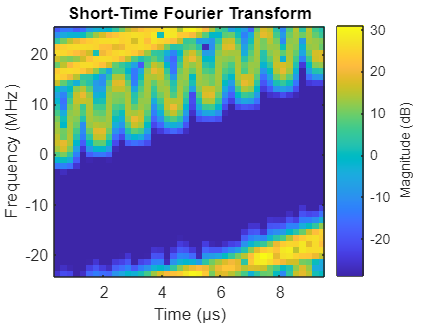

clear
clc

load('wave_data.mat');
fs = 5e7;
t_sample = 0 : 1/fs : 1e-5;
x = my_chirp(1e-5,15e6,35e6,fs);
% x = chirp(t_sample, 15e6, 1e-5, 35e6, 'complex');
% stft(x, fs, "Window", hann(40,'periodic'));
% y = chirp(t_sample,20e6, 1e-5, 32e6, 'complex');
y = my_chirp(1e-5,20e6,32e6,fs);
z = x + y;
z = z(1:500);
z = z + wave_data;
stft(z, fs,"Window",hann(42,'periodic'));